clc
clear all
close all
warning off

X = readtable('data_final.csv');
countLevels = @(x)numel(categories(categorical(x)));
numLevels = varfun(countLevels,X,'OutputFormat','uniform');

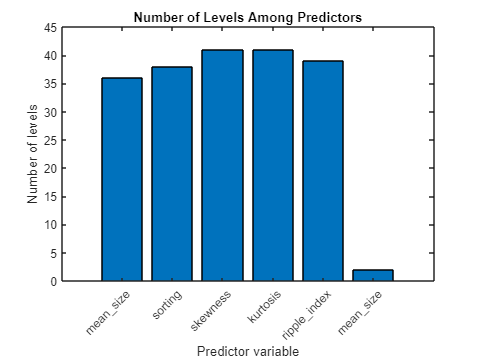

figure
bar(numLevels)
title('Number of Levels Among Predictors')
xlabel('Predictor variable')
ylabel('Number of levels')
h = gca;
h.XTickLabel = X.Properties.VariableNames(1:end-1);
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

t = templateTree('NumVariablesToSample','all','PredictorSelection','interaction-curvature','Surrogate','on');
rng(1); % For reproducibility
Mdl = fitrensemble(X,'zone','Method','Bag','NumLearningCycles',100,'Learners',t);

yHat = oobPredict(Mdl);
R2 = corr(Mdl.Y,yHat)^2

R2 = 0.8897

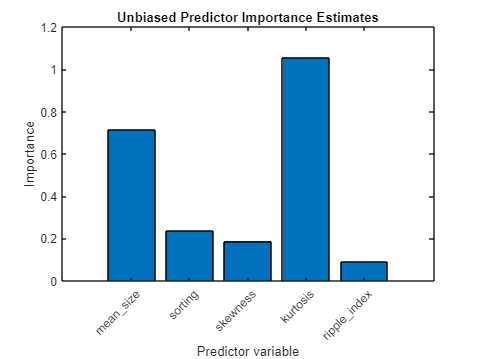

impOOB = oobPermutedPredictorImportance(Mdl);
figure
bar(impOOB)
title('Unbiased Predictor Importance Estimates')
xlabel('Predictor variable')
ylabel('Importance')
h = gca;
h.XTickLabel = Mdl.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

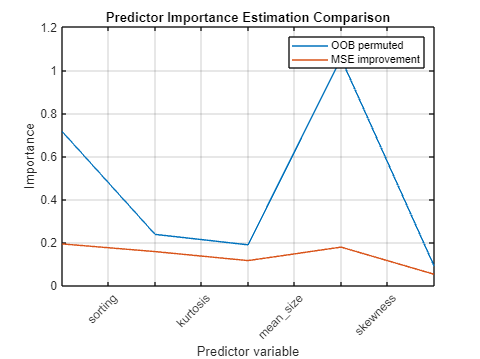

[impGain,predAssociation] = predictorImportance(Mdl);
figure
plot(1:numel(Mdl.PredictorNames),[impOOB' impGain'])
title('Predictor Importance Estimation Comparison')
xlabel('Predictor variable')
ylabel('Importance')
h = gca;
h.XTickLabel = Mdl.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';
legend('OOB permuted','MSE improvement')
grid on

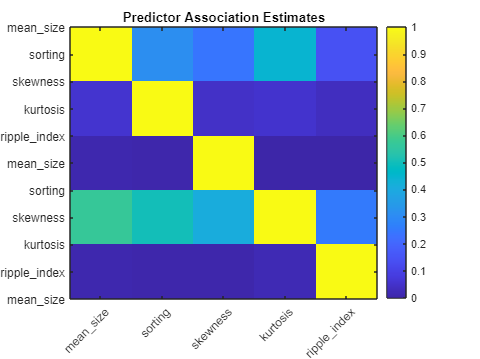

figure
imagesc(predAssociation)
title('Predictor Association Estimates')
colorbar
h = gca;
h.XTickLabel = Mdl.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';
h.YTickLabel = Mdl.PredictorNames;

cv = cvpartition(size(X,1),'HoldOut',0.3);
% allocating 30% of the data as test data
idx = cv.test;
dataTrain = X(~idx,:);
dataTest = X(idx,:);

% Specifying paramters to be used for test dataset
testing = dataTest(1:end,1:end-1);
model = fitensemble(dataTrain,'zone','Bag',100,'Tree','Type','classification');
prediction = predict(model,testing);
% ms = accuracy of model using given data
ms = (sum(prediction==table2array(dataTest(:,end)))/size(dataTest,1))*100

ms = 91.6667

disp(prediction)

     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     0



disp(testing)

    mean_size    sorting    skewness    kurtosis    ripple_index
    _________    _______    ________    ________    ____________

       3.3        0.408      -0.139       1.02          6.93    
      2.85        0.469      -0.004      0.847          6.38    
      2.99        0.417        0.33      0.991           6.7    
      3.33        0.465      -0.251      0.991          6.17    
      2.74         0.28       0.383      1.332          8.86    
      2.76        0.282       0.367      1.187           4.7    
       2.5        0.262       0.111      1.366          5.33    
      2.58        0.191       0.221      1.398          7.04    
      2.64        0.234       0.843       1.62           4.4    
      2.77        0.256       0.386      1.195           8.1    
       2.7        0.262       0.369       1.78   

mean_size_disp = [testing.mean_size];
% Task: use PCA instead of manual inputs
combined_disp = [testing.sorting*impOOB(1,2) + testing.skewness*impOOB(1,3) + testing.kurtosis*impOOB(1,4) + testing.ripple_index*impOOB(1,5)];
zone_disp = [prediction];
Y = table (mean_size_disp,combined_disp, zone_disp)

Y = 12×3 table
    mean_size_disp    combined_disp    zone_disp
    ______________    _____________    _________

          3.3            1.7648            1    
         2.85            1.5731            1    
         2.99            1.8039            1    
         3.33            1.6587            1    
         2.74             2.334            0    
         2.76            1.8066            0    
          2.5            1.9988            0    
         2.58            2.1893            0    
         2.64            2.3142            0    
         2.77            2.1165            1    
          2.7            2.7286            0    
         2.63            2.3537            0    


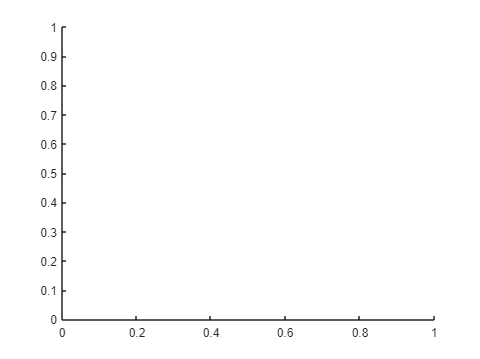

Error using gscatter
There must be one value of G for each row of X.

disp_model = fitensemble(Y,'zone_disp','Bag',100,'Tree','Type','classification');
e = min(Y.mean_size_disp):0.01:max(Y.mean_size_disp);
f = min(Y.combined_disp):0.01:max(Y.combined_disp);
[mg1 mg2] = meshgrid(e,f);
mg = [mg1(:) mg2(:)];
Z = 
gscatter(mg1(:),mg2(:),Z,'cy');

%hold on;
%gscatter(dataTrain.kurtosis,dataTrain.mean_size,dataTrain.zone,'rg','.',30);